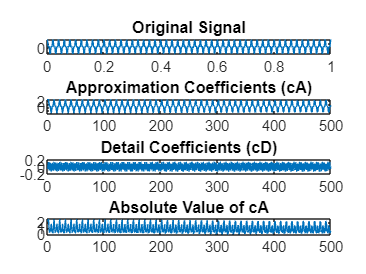

% Generate a sample electrical signal (replace this with your own data)
t = linspace(0, 1, 1000);  % Time vector from 0 to 1 with 1000 points
f = 50;  % Frequency of the electrical signal (50 Hz)
y = cos(2*pi*f*t) + 0.5*cos(2*pi*150*t) + 0.25*cos(2*pi*69);  % Example signal with 50 Hz and 150 Hz components

% Define the wavelet and level of decomposition
wavelet = 'db4';  % Daubechies wavelet, order 4
level = 3;  % Level of decomposition

% Perform DWT
[cA, cD] = dwt(y, wavelet, 'mode', 'per', 'level', level);

% cA contains the approximation coefficients (low-pass filtered component)
% cD contains the detail coefficients (high-pass filtered component)

% Plot the original signal and its DWT components
figure;
subplot(4,1,1); plot(t, y); title('Original Signal');
subplot(4,1,2); plot(cA); title('Approximation Coefficients (cA)');
subplot(4,1,3); plot(cD); title('Detail Coefficients (cD)');
subplot(4,1,4); plot(abs(cA)); title('Absolute Value of cA');

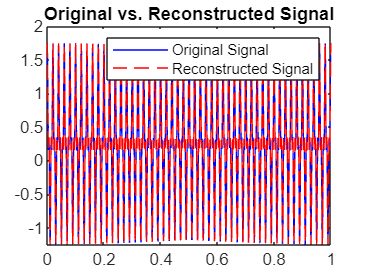


% Plot of the reconstructed signal
y_reconstructed = idwt(cA, cD, wavelet, 'mode', 'per');

% Plot the reconstructed signal
figure;
plot(t, y, 'b', t, y_reconstructed, 'r--');
legend('Original Signal', 'Reconstructed Signal');
title('Original vs. Reconstructed Signal');


% Calculate reconstruction error (optional)
error = norm(y - y_reconstructed);
disp(['Reconstruction error: ', num2str(error)]);

Reconstruction error: 2.3382e-11
